# Speech Processing

**TO DO: The provided files from the TIMIT database are sampled at 16kHz. Using Matlab, resample the files to 12 kHz, 8 kHz, 4 kHz, 2 kHz, and 1 kHz. Include a plot of the speech spectrum for each sampling rate.**

We solved this in three steps:

- Step1: Reading the given data set.

close all
clear all
clc 
warning off;
[x1,Fs1] = audioread("sx108.wav");
[x2,Fs2] = audioread("si1188.wav");
[x3,Fs3] = audioread("si1818.wav");
[x4,Fs4] = audioread("si558.wav");
[x5,Fs5] = audioread("sa2.wav");

t1 = [1:length(x1)]/Fs1;
t2 = [1:length(x2)]/Fs2;
t3 = [1:length(x3)]/Fs3;
t4 = [1:length(x4)]/Fs4;
t5 = [1:length(x5)]/Fs5;

f1 = linspace(0, Fs1, length(x1));
f2 = linspace(0, Fs2, length(x2));
f3 = linspace(0, Fs3, length(x3));
f4 = linspace(0, Fs4, length(x4));
f5 = linspace(0, Fs5, length(x5));

- Step 2: Resapling the audios to specified frequencies

new_x1_12kHz = resample(x1,3,4);
new_x1_8kHz = resample(x1,1,2);
new_x1_4kHz = resample(x1,1,4);
new_x1_2kHz = resample(x1,1,8);
new_x1_1kHz = resample(x1,1,16);
%----
new_x2_12kHz = resample(x2,3,4);
new_x2_8kHz = resample(x2,1,2);
new_x2_4kHz = resample(x2,1,4);
new_x2_2kHz = resample(x2,1,8);
new_x2_1kHz = resample(x2,1,16);
%----
new_x3_12kHz = resample(x3,3,4);
new_x3_8kHz = resample(x3,1,2);
new_x3_4kHz = resample(x3,1,4);
new_x3_2kHz = resample(x3,1,8);
new_x3_1kHz = resample(x3,1,16);
%----
new_x4_12kHz = resample(x4,3,4);
new_x4_8kHz = resample(x4,1,2);
new_x4_4kHz = resample(x4,1,4);
new_x4_2kHz = resample(x4,1,8);
new_x4_1kHz = resample(x4,1,16);
%----
new_x5_12kHz = resample(x5,3,4);
new_x5_8kHz = resample(x5,1,2);
new_x5_4kHz = resample(x5,1,4);
new_x5_2kHz = resample(x5,1,8);
new_x5_1kHz = resample(x5,1,16);

- Step 3: Frequency spectrum representation

Freqx1 = abs(fft(x1));
Freqx2 = abs(fft(x2));
Freqx3 = abs(fft(x3));
Freqx4 = abs(fft(x4));
Freqx5 = abs(fft(x5));
%----
Freq_new_X1_12kHz = abs(fft(new_x1_12kHz));
Freq_new_X1_8kHz = abs(fft(new_x1_8kHz));
Freq_new_X1_4kHz = abs(fft(new_x1_4kHz));
Freq_new_X1_2kHz = abs(fft(new_x1_2kHz));
Freq_new_X1_1kHz = abs(fft(new_x1_1kHz));
%----
Freq_new_X2_12kHz = abs(fft(new_x2_12kHz));
Freq_new_X2_8kHz = abs(fft(new_x2_8kHz));
Freq_new_X2_4kHz = abs(fft(new_x2_4kHz));
Freq_new_X2_2kHz = abs(fft(new_x2_2kHz));
Freq_new_X2_1kHz = abs(fft(new_x2_1kHz));
%----
Freq_new_X3_12kHz = abs(fft(new_x3_12kHz));
Freq_new_X3_8kHz = abs(fft(new_x3_8kHz));
Freq_new_X3_4kHz = abs(fft(new_x3_4kHz));
Freq_new_X3_2kHz = abs(fft(new_x3_2kHz));
Freq_new_X3_1kHz = abs(fft(new_x3_1kHz));
%----
Freq_new_X4_12kHz = abs(fft(new_x4_12kHz));
Freq_new_X4_8kHz = abs(fft(new_x4_8kHz));
Freq_new_X4_4kHz = abs(fft(new_x4_4kHz));
Freq_new_X4_2kHz = abs(fft(new_x4_2kHz));
Freq_new_X4_1kHz = abs(fft(new_x4_1kHz));
%----
Freq_new_X5_12kHz = abs(fft(new_x5_12kHz));
Freq_new_X5_8kHz = abs(fft(new_x5_8kHz));
Freq_new_X5_4kHz = abs(fft(new_x5_4kHz));
Freq_new_X5_2kHz = abs(fft(new_x5_2kHz));
Freq_new_X5_1kHz = abs(fft(new_x5_1kHz));



- Plotting:

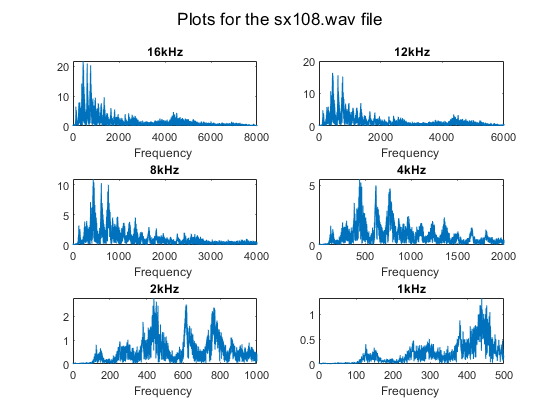


figure
subplot(3,2,1)
plot(f1(1:length(x1)/2),Freqx1(1:length(x1)/2))
title('16kHz')
xlabel('Frequency ')
subplot(3,2,2)
plot(f1(1:length(new_x1_12kHz)/2),Freq_new_X1_12kHz(1:length(new_x1_12kHz)/2))
title('12kHz')
xlabel('Frequency ')
subplot(3,2,3)
plot(f1(1:length(new_x1_8kHz)/2),Freq_new_X1_8kHz(1:length(new_x1_8kHz)/2))
title('8kHz')
xlabel('Frequency ')
subplot(3,2,4)
plot(f1(1:length(new_x1_4kHz)/2),Freq_new_X1_4kHz(1:length(new_x1_4kHz)/2))
title('4kHz')
xlabel('Frequency ')
subplot(3,2,5)
plot(f1(1:length(new_x1_2kHz)/2),Freq_new_X1_2kHz(1:length(new_x1_2kHz)/2))
title('2kHz')
xlabel('Frequency ')
subplot(3,2,6)
plot(f1(1:length(new_x1_1kHz)/2),Freq_new_X1_1kHz(1:length(new_x1_1kHz)/2))
title('1kHz')
xlabel('Frequency ')
sgtitle('Plots for the sx108.wav file') 

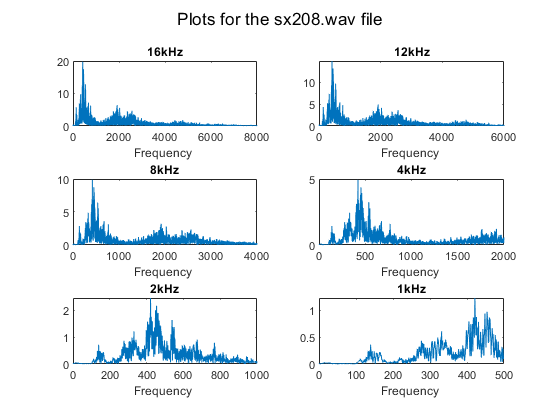


figure
subplot(3,2,1)
plot(f2(1:length(x2)/2),Freqx2(1:length(x2)/2))
title('16kHz')
xlabel('Frequency ')
subplot(3,2,2)
plot(f2(1:length(new_x2_12kHz)/2),Freq_new_X2_12kHz(1:length(new_x2_12kHz)/2))
title('12kHz')
xlabel('Frequency ')
subplot(3,2,3)
plot(f2(1:length(new_x2_8kHz)/2),Freq_new_X2_8kHz(1:length(new_x2_8kHz)/2))
title('8kHz')
xlabel('Frequency ')
subplot(3,2,4)
plot(f2(1:length(new_x2_4kHz)/2),Freq_new_X2_4kHz(1:length(new_x2_4kHz)/2))
title('4kHz')
xlabel('Frequency ')
subplot(3,2,5)
plot(f2(1:length(new_x2_2kHz)/2),Freq_new_X2_2kHz(1:length(new_x2_2kHz)/2))
title('2kHz')
xlabel('Frequency ')
subplot(3,2,6)
plot(f2(1:length(new_x2_1kHz)/2),Freq_new_X2_1kHz(1:length(new_x2_1kHz)/2))
title('1kHz')
xlabel('Frequency ')
sgtitle('Plots for the sx208.wav file') 

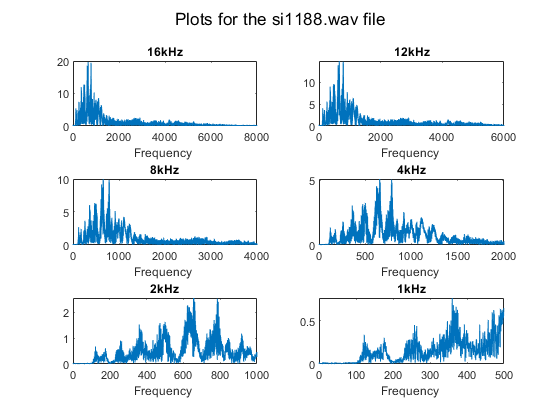


figure
subplot(3,2,1)
plot(f3(1:length(x3)/2),Freqx3(1:length(x3)/2))
title('16kHz')
xlabel('Frequency ')
subplot(3,2,2)
plot(f3(1:length(new_x3_12kHz)/2),Freq_new_X3_12kHz(1:length(new_x3_12kHz)/2))
title('12kHz')
xlabel('Frequency ')
subplot(3,2,3)
plot(f3(1:length(new_x3_8kHz)/2),Freq_new_X3_8kHz(1:length(new_x3_8kHz)/2))
title('8kHz')
xlabel('Frequency ')
subplot(3,2,4)
plot(f3(1:length(new_x3_4kHz)/2),Freq_new_X3_4kHz(1:length(new_x3_4kHz)/2))
title('4kHz')
xlabel('Frequency ')
subplot(3,2,5)
plot(f3(1:length(new_x3_2kHz)/2),Freq_new_X3_2kHz(1:length(new_x3_2kHz)/2))
title('2kHz')
xlabel('Frequency ')
subplot(3,2,6)
plot(f3(1:length(new_x3_1kHz)/2),Freq_new_X3_1kHz(1:length(new_x3_1kHz)/2))
title('1kHz')
xlabel('Frequency ')
sgtitle('Plots for the si1188.wav file') 

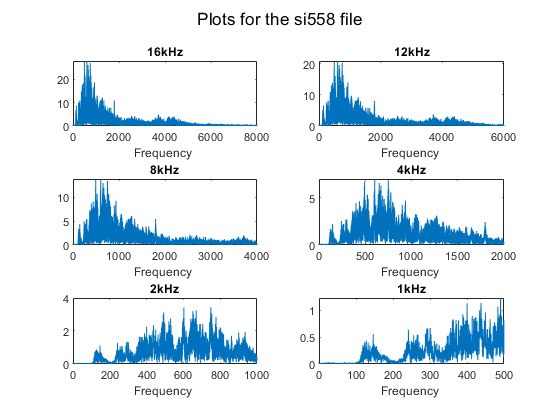


figure
subplot(3,2,1)
plot(f4(1:length(x4)/2),Freqx4(1:length(x4)/2))
title('16kHz')
xlabel('Frequency ')
subplot(3,2,2)
plot(f4(1:length(new_x4_12kHz)/2),Freq_new_X4_12kHz(1:length(new_x4_12kHz)/2))
title('12kHz')
xlabel('Frequency ')
subplot(3,2,3)
plot(f4(1:length(new_x4_8kHz)/2),Freq_new_X4_8kHz(1:length(new_x4_8kHz)/2))
title('8kHz')
xlabel('Frequency ')
subplot(3,2,4)
plot(f4(1:length(new_x4_4kHz)/2),Freq_new_X4_4kHz(1:length(new_x4_4kHz)/2))
title('4kHz')
xlabel('Frequency ')
subplot(3,2,5)
plot(f4(1:length(new_x4_2kHz)/2),Freq_new_X4_2kHz(1:length(new_x4_2kHz)/2))
title('2kHz')
xlabel('Frequency ')
subplot(3,2,6)
plot(f4(1:length(new_x4_1kHz)/2),Freq_new_X4_1kHz(1:length(new_x4_1kHz)/2))
title('1kHz')
xlabel('Frequency ')
sgtitle('Plots for the si558 file') 

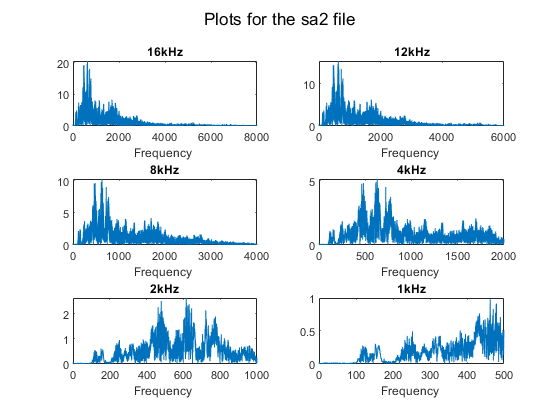


figure
subplot(3,2,1)
plot(f5(1:length(x5)/2),Freqx5(1:length(x5)/2))
title('16kHz')
xlabel('Frequency ')
subplot(3,2,2)
plot(f5(1:length(new_x5_12kHz)/2),Freq_new_X5_12kHz(1:length(new_x5_12kHz)/2))
title('12kHz')
xlabel('Frequency ')
subplot(3,2,3)
plot(f5(1:length(new_x5_8kHz)/2),Freq_new_X5_8kHz(1:length(new_x5_8kHz)/2))
title('8kHz')
xlabel('Frequency ')
subplot(3,2,4)
plot(f5(1:length(new_x5_4kHz)/2),Freq_new_X5_4kHz(1:length(new_x5_4kHz)/2))
title('4kHz')
xlabel('Frequency ')
subplot(3,2,5)
plot(f5(1:length(new_x5_2kHz)/2),Freq_new_X5_2kHz(1:length(new_x5_2kHz)/2))
title('2kHz')
xlabel('Frequency ')
subplot(3,2,6)
plot(f5(1:length(new_x5_1kHz)/2),Freq_new_X5_1kHz(1:length(new_x5_1kHz)/2))
title('1kHz')
xlabel('Frequency ')
sgtitle('Plots for the sa2 file') 

- The intelligibility begins to decrease for sampling frequencies below 4kHz. 

- This happens because we are reducing the samples, which results in loss of information. 

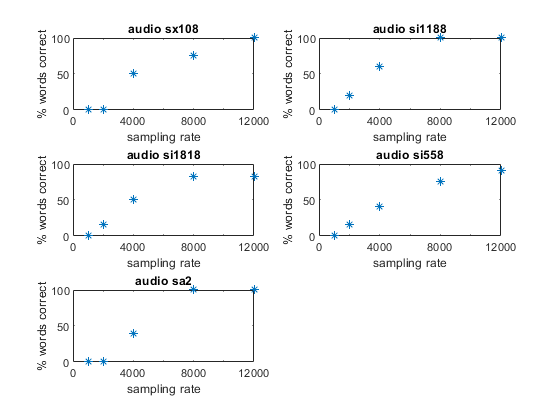

sampling_rate = [1000 2000 4000 8000 12000];

audior1 = [0 0 0.5 0.75 1].*100;
audior2 = [0 0.2 0.6 1 1].*100;
audior3 = [0 0.16 0.5 0.83 0.83].*100;
audior4 = [0 0.16 0.41 0.75 0.91].*100;
audior5 = [0 0 0.4 1 1].*100;

figure()
subplot(321)
plot(sampling_rate,audior1,'*')
xlabel('sampling rate')
ylabel('% words correct')
title('audio sx108')

subplot(322)
plot(sampling_rate,audior2,'*')
xlabel('sampling rate')
ylabel('% words correct')
title('audio si1188')

subplot(323)
plot(sampling_rate,audior3,'*')
xlabel('sampling rate')
ylabel('% words correct')
title('audio si1818')

subplot(324)
plot(sampling_rate,audior4,'*')
xlabel('sampling rate')
ylabel('% words correct')
title('audio si558')

subplot(325)
plot(sampling_rate,audior5,'*')
xlabel('sampling rate')
ylabel('% words correct')
title('audio sa2')

**TO DO: The provided files from the TIMIT database are represented with 16 bits per sample (bps). Using Matlab, reduce the samples to 12 bps, 8 bps, 4bps, 2 bps, and 1 bps. Include a plot of the speech spectrum and the time domain signal for each bit rate.**

We solved this in two steps: 

- Step 1: Reducing bit rate.

x1_16bits = double(uencode(x1,16))/(2^16);
x1_16bits = 2*(x1_16bits-mean(x1_16bits));
x1_12bits = double(uencode(x1,12))/(2^12);
x1_12bits = 2*(x1_12bits-mean(x1_12bits));
x1_8bits = double(uencode(x1,8))/(2^8);
x1_8bits = 2*(x1_8bits-mean(x1_8bits));
x1_4bits = double(uencode(x1,4))/(2^4);
x1_4bits = 2*(x1_4bits-mean(x1_4bits));
x1_2bits = double(uencode(x1,2))/(2^2);
x1_2bits = 2*(x1_2bits-mean(x1_2bits));
min_x1 = min(x1);
max_x1 = max(x1);
Thres_x1 = mean([min_x1,max_x1]);
for i = 1:length(x1)
    if x1(i)>Thres_x1 
        x1_1bits(i) = 1;
    else
        x1_1bits(i) = -1;
    end
end
%---
x2_16bits = double(uencode(x2,16))/(2^16);
x2_16bits = 2*(x2_16bits-mean(x2_16bits));
x2_12bits = double(uencode(x2,12))/(2^12);
x2_12bits = 2*(x2_12bits-mean(x2_12bits));
x2_8bits = double(uencode(x2,8))/(2^8);
x2_8bits = 2*(x2_8bits-mean(x2_8bits));
x2_4bits = double(uencode(x2,4))/(2^4);
x2_4bits = 2*(x2_4bits-mean(x2_4bits));
x2_2bits = double(uencode(x2,2))/(2^2);
x2_2bits = 2*(x2_2bits-mean(x2_2bits));
min_x2 = min(x2);
max_x2 = max(x2);
Thres_x2 = mean([min_x2,max_x2]);
for i = 1:length(x2)
    if x2(i)>Thres_x2 
        x2_1bits(i) = 1;
    else
        x2_1bits(i) = -1;
    end
end

%---
x3_16bits = double(uencode(x3,16))/(2^16);
x3_16bits = 2*(x3_16bits-mean(x3_16bits));
x3_12bits = double(uencode(x3,12))/(2^12);
x3_12bits = 2*(x3_12bits-mean(x3_12bits));
x3_8bits = double(uencode(x3,8))/(2^8);
x3_8bits = 2*(x3_8bits-mean(x3_8bits));
x3_4bits = double(uencode(x3,4))/(2^4);
x3_4bits = 2*(x3_4bits-mean(x3_4bits));
x3_2bits = double(uencode(x3,2))/(2^2);
x3_2bits = 2*(x3_2bits-mean(x3_2bits));
min_x3 = min(x3);
max_x3 = max(x3);
Thres_x3 = mean([min_x3,max_x3]);
for i = 1:length(x3)
    if x3(i)>Thres_x3 
        x3_1bits(i) = 1;
    else
        x3_1bits(i) = -1;
    end
end

%---
x4_16bits = double(uencode(x4,16))/(2^16);
x4_16bits = 2*(x4_16bits-mean(x4_16bits));
x4_12bits = double(uencode(x4,12))/(2^12);
x4_12bits = 2*(x4_12bits-mean(x4_12bits));
x4_8bits = double(uencode(x4,8))/(2^8);
x4_8bits = 2*(x4_8bits-mean(x4_8bits));
x4_4bits = double(uencode(x4,4))/(2^4);
x4_4bits = 2*(x4_4bits-mean(x4_4bits));
x4_2bits = double(uencode(x4,2))/(2^2);
x4_2bits = 2*(x4_2bits-mean(x4_2bits));
min_x4 = min(x4);
max_x4 = max(x4);
Thres_x4 = mean([min_x4,max_x4]);
for i = 1:length(x4)
    if x4(i)>Thres_x4 
        x4_1bits(i) = 1;
    else
        x4_1bits(i) = -1;
    end
end
%---
x5_16bits = double(uencode(x5,16))/(2^16);
x5_16bits = 2*(x5_16bits-mean(x5_16bits));
x5_12bits = double(uencode(x5,12))/(2^12);
x5_12bits = 2*(x5_12bits-mean(x5_12bits));
x5_8bits = double(uencode(x5,8))/(2^8);
x5_8bits = 2*(x5_8bits-mean(x5_8bits));
x5_4bits = double(uencode(x5,4))/(2^4);
x5_4bits = 2*(x5_4bits-mean(x5_4bits));
x5_2bits = double(uencode(x5,2))/(2^2);
x5_2bits = 2*(x5_2bits-mean(x5_2bits));
min_x5 = min(x5);
max_x5 = max(x5);
Thres_x5 = mean([min_x5,max_x5]);
for i = 1:length(x5)
    if x5(i)>Thres_x5 
        x5_1bits(i) = 1;
    else
        x5_1bits(i) = -1;
    end
end

- Step 2: frequency representation.

Freq_new_x1_12bits = abs(fft(x1_12bits));
Freq_new_x1_8bits = abs(fft(x1_8bits));
Freq_new_x1_4bits = abs(fft(x1_4bits));
Freq_new_x1_2bits = abs(fft(x1_2bits));
Freq_new_x1_1bits = abs(fft(x1_1bits'));

Freq_new_x2_12bits = abs(fft(x2_12bits));
Freq_new_x2_8bits = abs(fft(x2_8bits));
Freq_new_x2_4bits = abs(fft(x2_4bits));
Freq_new_x2_2bits = abs(fft(x2_2bits));
Freq_new_x2_1bits = abs(fft(x2_1bits'));

Freq_new_x3_12bits = abs(fft(x3_12bits));
Freq_new_x3_8bits = abs(fft(x3_8bits));
Freq_new_x3_4bits = abs(fft(x3_4bits));
Freq_new_x3_2bits = abs(fft(x3_2bits));
Freq_new_x3_1bits = abs(fft(x3_1bits'));


Freq_new_x4_12bits = abs(fft(x4_12bits));
Freq_new_x4_8bits = abs(fft(x4_8bits));
Freq_new_x4_4bits = abs(fft(x4_4bits));
Freq_new_x4_2bits = abs(fft(x4_2bits));
Freq_new_x4_1bits = abs(fft(x4_1bits'));

Freq_new_x5_12bits = abs(fft(x5_12bits));
Freq_new_x5_8bits = abs(fft(x5_8bits));
Freq_new_x5_4bits = abs(fft(x5_4bits));
Freq_new_x5_2bits = abs(fft(x5_2bits));
Freq_new_x5_1bits = abs(fft(x5_1bits'));

- Plotting:

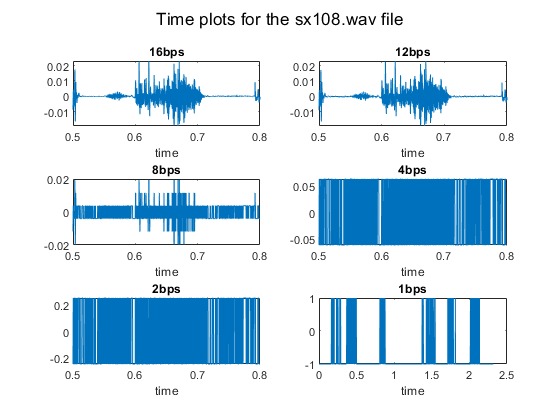

figure
subplot(321)
plot(t1,x1_16bits)
xlim([0.5 0.8])
xlabel('time')
title('16bps')
subplot(322)
plot(t1,x1_12bits)
xlim([0.5 0.8])
xlabel('time')
title('12bps')
subplot(323)
plot(t1,x1_8bits)
xlim([0.5 0.8])
xlabel('time')
title('8bps')
subplot(324)
plot(t1,x1_4bits)
xlim([0.5 0.8])
xlabel('time')
title('4bps')
subplot(325)
plot(t1,x1_2bits)
xlim([0.5 0.8])
xlabel('time')
title('2bps')
subplot(326)
plot(t1,x1_1bits')

xlabel('time')
title('1bps')
sgtitle('Time plots for the sx108.wav file') 

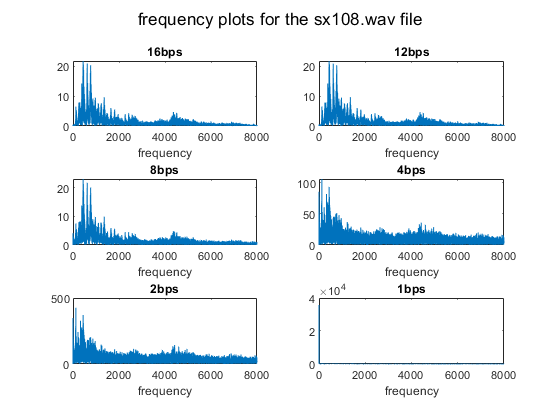


figure
subplot(321)
plot(f1(1:length(x1)/2),Freqx1(1:length(x1)/2))
% plot(Freqx1)
xlabel('frequency')
title('16bps')
subplot(322)
plot(f1(1:length(x1_12bits)/2),Freq_new_x1_12bits(1:length(x1_12bits)/2))
%plot(Freq_new_x1_12bits)
xlabel('frequency')
title('12bps')
subplot(323)
plot(f1(1:length(x1_8bits)/2),Freq_new_x1_8bits(1:length(x1_8bits)/2))
% plot(Freq_new_x1_8bits)
xlabel('frequency')
title('8bps')
subplot(324)
plot(f1(1:length(x1_4bits)/2),Freq_new_x1_4bits(1:length(x1_4bits)/2))
%plot(Freq_new_x1_4bits)
xlabel('frequency')
title('4bps')
subplot(325)
plot(f1(1:length(x1_2bits)/2),Freq_new_x1_2bits(1:length(x1_2bits)/2))
%plot(Freq_new_x1_2bits)
xlabel('frequency')
title('2bps')
subplot(326)
plot(f1(1:length(x1_1bits)/2),Freq_new_x1_1bits(1:length(x1_1bits)/2))
% plot(Freq_new_x1_1bits)
xlabel('frequency')
title('1bps')
sgtitle('frequency plots for the sx108.wav file') 

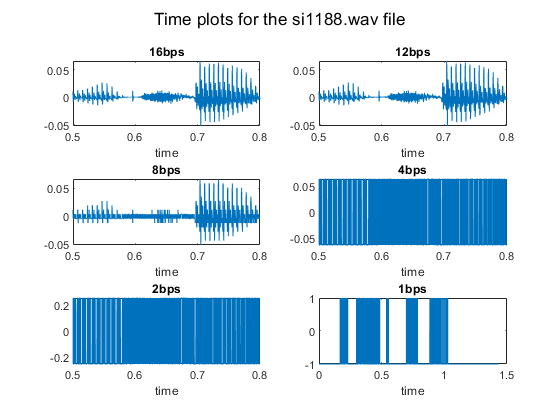

figure
subplot(321)
plot(t2,x2_16bits)
xlim([0.5 0.8])
xlabel('time')
title('16bps')
subplot(322)
plot(t2,x2_12bits)
xlim([0.5 0.8])
xlabel('time')
title('12bps')
subplot(323)
plot(t2,x2_8bits)
xlim([0.5 0.8])
xlabel('time')
title('8bps')
subplot(324)
plot(t2,x2_4bits)
xlim([0.5 0.8])
xlabel('time')
title('4bps')
subplot(325)
plot(t2,x2_2bits)
xlim([0.5 0.8])
xlabel('time')
title('2bps')
subplot(326)
plot(t2,x2_1bits')
xlabel('time')
title('1bps')
sgtitle('Time plots for the si1188.wav file') 

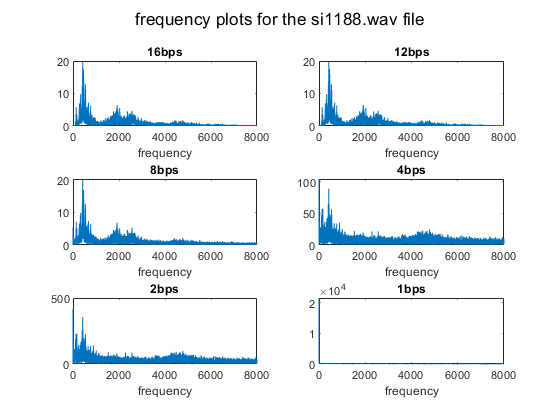


figure
subplot(321)
plot(f2(1:length(x2)/2),Freqx2(1:length(x2)/2))
% plot(Freqx2)
xlabel('frequency')
title('16bps')
subplot(322)
plot(f2(1:length(x2_12bits)/2),Freq_new_x2_12bits(1:length(x2_12bits)/2))
%plot(Freq_new_x2_12bits)
xlabel('frequency')
title('12bps')
subplot(323)
plot(f2(1:length(x2_8bits)/2),Freq_new_x2_8bits(1:length(x2_8bits)/2))
% plot(Freq_new_x2_8bits)
xlabel('frequency')
title('8bps')
subplot(324)
plot(f2(1:length(x2_4bits)/2),Freq_new_x2_4bits(1:length(x2_4bits)/2))
%plot(Freq_new_x2_4bits)
xlabel('frequency')
title('4bps')
subplot(325)
plot(f2(1:length(x2_2bits)/2),Freq_new_x2_2bits(1:length(x2_2bits)/2))
%plot(Freq_new_x2_2bits)
xlabel('frequency')
title('2bps')
subplot(326)
plot(f2(1:length(x2_1bits)/2),Freq_new_x2_1bits(1:length(x2_1bits)/2))
% plot(Freq_new_x2_1bits)

xlabel('frequency')
title('1bps')
sgtitle('frequency plots for the si1188.wav file') 

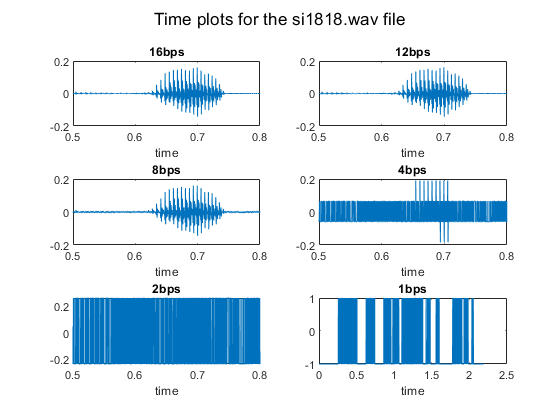


figure
subplot(321)
plot(t3,x3_16bits)
xlim([0.5 0.8])
xlabel('time')
title('16bps')
subplot(322)
plot(t3,x3_12bits)
xlim([0.5 0.8])
xlabel('time')
title('12bps')
subplot(323)
plot(t3,x3_8bits)
xlim([0.5 0.8])
xlabel('time')
title('8bps')
subplot(324)
plot(t3,x3_4bits)
xlim([0.5 0.8])
xlabel('time')
title('4bps')
subplot(325)
plot(t3,x3_2bits)
xlim([0.5 0.8])
xlabel('time')
title('2bps')
subplot(326)
plot(t3,x3_1bits')
xlabel('time')
title('1bps')
sgtitle('Time plots for the si1818.wav file') 

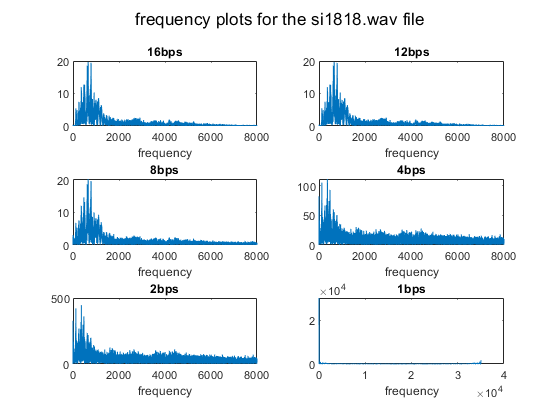



figure
subplot(321)
plot(f3(1:length(x3)/2),Freqx3(1:length(x3)/2))
% plot(Freqx3)
xlabel('frequency')
title('16bps')
subplot(322)
plot(f3(1:length(x3_12bits)/2),Freq_new_x3_12bits(1:length(x3_12bits)/2))
%plot(Freq_new_x3_12bits)
xlabel('frequency')
title('12bps')
subplot(323)
plot(f3(1:length(x3_8bits)/2),Freq_new_x3_8bits(1:length(x3_8bits)/2))
% plot(Freq_new_x3_8bits)
xlabel('frequency')
title('8bps')
subplot(324)
plot(f3(1:length(x3_4bits)/2),Freq_new_x3_4bits(1:length(x3_4bits)/2))
%plot(Freq_new_x3_4bits)
xlabel('frequency')
title('4bps')
subplot(325)
plot(f3(1:length(x3_2bits)/2),Freq_new_x3_2bits(1:length(x3_2bits)/2))
%plot(Freq_new_x3_2bits)
xlabel('frequency')
title('2bps')
subplot(326)
plot(f3(1:length(x3_1bits)/2),Freq_new_x3_1bits(1:length(x3_1bits)/2))
plot(Freq_new_x3_1bits)
xlabel('frequency')
title('1bps')
sgtitle('frequency plots for the si1818.wav file') 

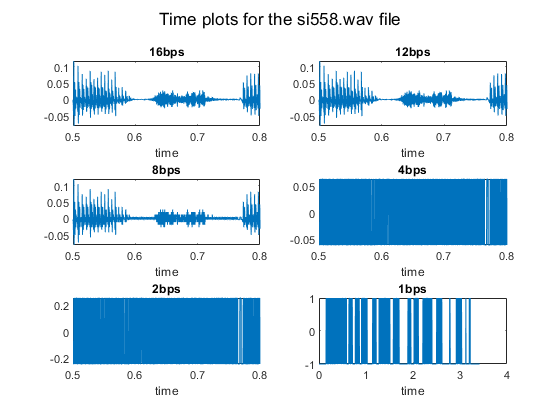


figure
subplot(321)
plot(t4,x4_16bits)
xlim([0.5 0.8])
xlabel('time')
title('16bps')
subplot(322)
plot(t4,x4_12bits)
xlim([0.5 0.8])
xlabel('time')
title('12bps')
subplot(323)
plot(t4,x4_8bits)
xlim([0.5 0.8])
xlabel('time')
title('8bps')
subplot(324)
plot(t4,x4_4bits)
xlim([0.5 0.8])
xlabel('time')
title('4bps')
subplot(325)
plot(t4,x4_2bits)
xlim([0.5 0.8])
xlabel('time')
title('2bps')
subplot(326)
plot(t4,x4_1bits')
xlabel('time')
title('1bps')
sgtitle('Time plots for the si558.wav file') 

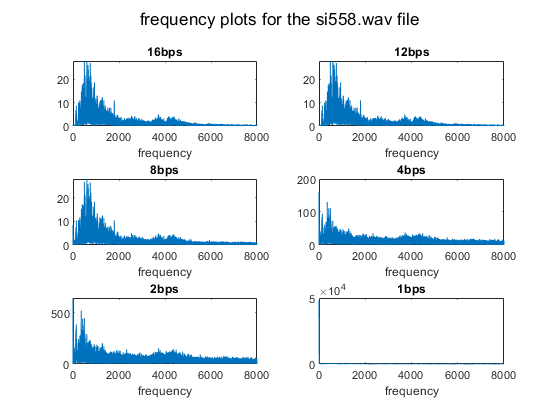




figure
subplot(321)
plot(f4(1:length(x4)/2),Freqx4(1:length(x4)/2))
% plot(Freqx4)
xlabel('frequency')
title('16bps')
subplot(322)
plot(f4(1:length(x4_12bits)/2),Freq_new_x4_12bits(1:length(x4_12bits)/2))
%plot(Freq_new_x4_12bits)
xlabel('frequency')
title('12bps')
subplot(323)
plot(f4(1:length(x4_8bits)/2),Freq_new_x4_8bits(1:length(x4_8bits)/2))
% plot(Freq_new_x4_8bits)
xlabel('frequency')
title('8bps')
subplot(324)
plot(f4(1:length(x4_4bits)/2),Freq_new_x4_4bits(1:length(x4_4bits)/2))
%plot(Freq_new_x4_4bits)
xlabel('frequency')
title('4bps')
subplot(325)
plot(f4(1:length(x4_2bits)/2),Freq_new_x4_2bits(1:length(x4_2bits)/2))
%plot(Freq_new_x4_2bits)
xlabel('frequency')
title('2bps')
subplot(326)
plot(f4(1:length(x4_1bits)/2),Freq_new_x4_1bits(1:length(x4_1bits)/2))
% plot(Freq_new_x4_1bits)
xlabel('frequency')
title('1bps')
sgtitle('frequency plots for the si558.wav file') 

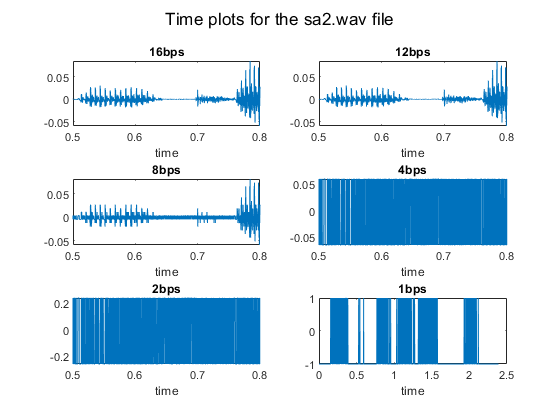


figure
subplot(321)
plot(t5,x5_16bits)
xlim([0.5 0.8])
xlabel('time')
title('16bps')
subplot(322)
plot(t5,x5_12bits)
xlim([0.5 0.8])
xlabel('time')
title('12bps')
subplot(323)
plot(t5,x5_8bits)
xlim([0.5 0.8])
xlabel('time')
title('8bps')
subplot(324)
plot(t5,x5_4bits)
xlim([0.5 0.8])
xlabel('time')
title('4bps')
subplot(325)
plot(t5,x5_2bits)
xlim([0.5 0.8])
xlabel('time')
title('2bps')
subplot(326)
plot(t5,x5_1bits')
xlabel('time')
title('1bps')
sgtitle('Time plots for the sa2.wav file') 

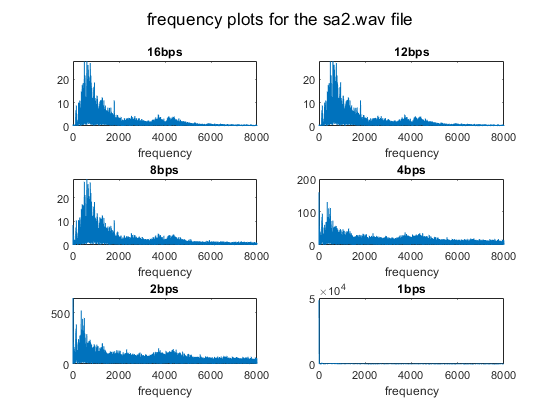



figure
subplot(321)
plot(f4(1:length(x4)/2),Freqx4(1:length(x4)/2))
% plot(Freqx4)
xlabel('frequency')
title('16bps')
subplot(322)
plot(f4(1:length(x4_12bits)/2),Freq_new_x4_12bits(1:length(x4_12bits)/2))
%plot(Freq_new_x4_12bits)
xlabel('frequency')
title('12bps')
subplot(323)
plot(f4(1:length(x4_8bits)/2),Freq_new_x4_8bits(1:length(x4_8bits)/2))
% plot(Freq_new_x4_8bits)
xlabel('frequency')
title('8bps')
subplot(324)
plot(f4(1:length(x4_4bits)/2),Freq_new_x4_4bits(1:length(x4_4bits)/2))
%plot(Freq_new_x4_4bits)
xlabel('frequency')
title('4bps')
subplot(325)
plot(f4(1:length(x4_2bits)/2),Freq_new_x4_2bits(1:length(x4_2bits)/2))
%plot(Freq_new_x4_2bits)
xlabel('frequency')
title('2bps')
subplot(326)
plot(f4(1:length(x4_1bits)/2),Freq_new_x4_1bits(1:length(x4_1bits)/2))
% plot(Freq_new_x4_1bits)
xlabel('frequency')
title('1bps')
sgtitle('frequency plots for the sa2.wav file') 

- The intelligibility begins to decrease for 4bps and gets very low at 2 bps and 1 bps.. As the quantization bits decrease, the actual signal  information captured in them decreases and hence we hear a noisy and jittery audio.

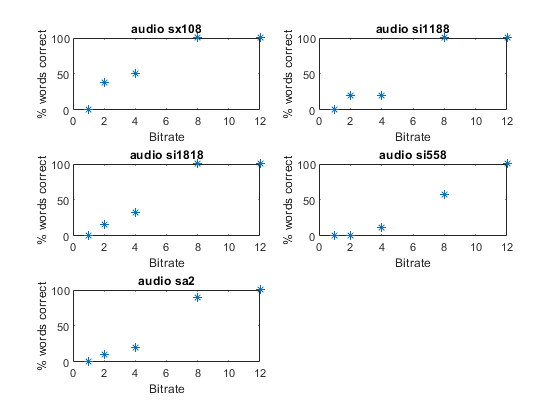

bitrate = [1 2 4 8 12];

audio1 = [0 0.375 0.5 1 1].*100;
audio2 = [0 0.2 0.2 1 1].*100;
audio3 = [0 0.16 0.33 1 1].*100;
audio4 = [0 0 0.12 0.58 1].*100;
audio5 = [0 0.1 0.2 0.9 1].*100;

figure()
subplot(321)
plot(bitrate,audio1,'*')
xlabel('Bitrate')
ylabel('% words correct')
title('audio sx108')

subplot(322)
plot(bitrate,audio2,'*')
xlabel('Bitrate')
ylabel('% words correct')
title('audio si1188')

subplot(323)
plot(bitrate,audio3,'*')
xlabel('Bitrate')
ylabel('% words correct')
title('audio si1818')

subplot(324)
plot(bitrate,audio4,'*')
xlabel('Bitrate')
ylabel('% words correct')
title('audio si558')

subplot(325)
plot(bitrate,audio5,'*')
xlabel('Bitrate')
ylabel('% words correct')
title('audio sa2')

**TO DO: For the five different quantization levels in the previous question, calculate the SNR **

**We solved this in the following steps:**

- Step 1: Calculation the energy of the original signal and the residual signal. 

- Step 2: Then calcuting the SNR:

energy_signal_x1 = [sum(x1.^2) sum(x1.^2) sum(x1.^2) sum(x1.^2) sum(x1.^2)];
res_signal_x1 = [x1-x1_16bits x1-x1_12bits x1-x1_8bits x1-x1_4bits x1-x1_2bits] ;
energy_res_signal_x1 = [sum(res_signal_x1(:,1).^2) sum(res_signal_x1(:,2).^2) sum(res_signal_x1(:,3).^2) sum(res_signal_x1(:,4).^2) sum(res_signal_x1(:,5).^2)];
SNR = energy_signal_x1./energy_res_signal_x1;
SNR_dB_x1 = 10*log10(SNR);
quan_lvls = [16 12 8 4 2];


energy_signal_x2 = [sum(x2.^2) sum(x2.^2) sum(x2.^2) sum(x2.^2) sum(x2.^2)];
res_signal_x2 = [x2-x2_16bits x2-x2_12bits x2-x2_8bits x2-x2_4bits x2-x2_2bits] ;
energy_res_signal_x2 = [sum(res_signal_x2(:,1).^2) sum(res_signal_x2(:,2).^2) sum(res_signal_x2(:,3).^2) sum(res_signal_x2(:,4).^2) sum(res_signal_x2(:,5).^2)];
SNR = energy_signal_x2./energy_res_signal_x2;
SNR_dB_x2 = 10*log10(SNR);
quan_lvls = [16 12 8 4 2];



energy_signal_x3 = [sum(x3.^2) sum(x3.^2) sum(x3.^2) sum(x3.^2) sum(x3.^2)];
res_signal_x3 = [x3-x3_16bits x3-x3_12bits x3-x3_8bits x3-x3_4bits x3-x3_2bits] ;
energy_res_signal_x3 = [sum(res_signal_x3(:,1).^2) sum(res_signal_x3(:,2).^2) sum(res_signal_x3(:,3).^2) sum(res_signal_x3(:,4).^2) sum(res_signal_x3(:,5).^2)];
SNR = energy_signal_x3./energy_res_signal_x3;
SNR_dB_x3 = 10*log10(SNR);
quan_lvls = [16 12 8 4 2];



energy_signal_x4 = [sum(x4.^2) sum(x4.^2) sum(x4.^2) sum(x4.^2) sum(x4.^2)];
res_signal_x4 = [x4-x4_16bits x4-x4_12bits x4-x4_8bits x4-x4_4bits x4-x4_2bits] ;
energy_res_signal_x4 = [sum(res_signal_x4(:,1).^2) sum(res_signal_x4(:,2).^2) sum(res_signal_x4(:,3).^2) sum(res_signal_x4(:,4).^2) sum(res_signal_x4(:,5).^2)];
SNR = energy_signal_x4./energy_res_signal_x4;
SNR_dB_x4 = 10*log10(SNR);
quan_lvls = [16 12 8 4 2];



energy_signal_x5 = [sum(x5.^2) sum(x5.^2) sum(x5.^2) sum(x5.^2) sum(x5.^2)];
res_signal_x5 = [x5-x5_16bits x5-x5_12bits x5-x5_8bits x5-x5_4bits x5-x5_2bits] ;
energy_res_signal_x5 = [sum(res_signal_x5(:,1).^2) sum(res_signal_x5(:,2).^2) sum(res_signal_x5(:,3).^2) sum(res_signal_x5(:,4).^2) sum(res_signal_x5(:,5).^2)];
SNR = energy_signal_x5./energy_res_signal_x5;
SNR_dB_x5 = 10*log10(SNR);
quan_lvls = [16 12 8 4 2];

- Ploting:

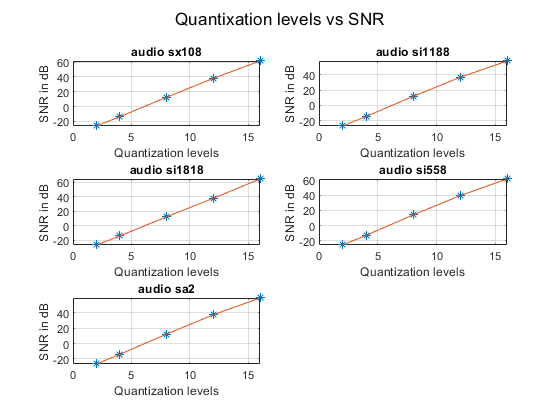

figure()
subplot(321)
plot(quan_lvls,SNR_dB_x1,'*',quan_lvls,SNR_dB_x1)
xlabel('Quantization levels')
ylabel('SNR in dB')
title('audio sx108')
grid on
subplot(322)
plot(quan_lvls,SNR_dB_x2,'*',quan_lvls,SNR_dB_x2)
xlabel('Quantization levels')
ylabel('SNR in dB')
title('audio si1188')
grid on
subplot(323)
plot(quan_lvls,SNR_dB_x3,'*',quan_lvls,SNR_dB_x3)
xlabel('Quantization levels')
ylabel('SNR in dB')
title('audio si1818')
grid on
subplot(324)
plot(quan_lvls,SNR_dB_x4,'*',quan_lvls,SNR_dB_x4)
xlabel('Quantization levels')
ylabel('SNR in dB')
title('audio si558')
grid on
subplot(325)
plot(quan_lvls,SNR_dB_x5,'*',quan_lvls,SNR_dB_x5)
xlabel('Quantization levels')
ylabel('SNR in dB')
title('audio sa2')
grid on
sgtitle('Quantixation levels vs SNR')

**TO DO: . Simulate high-frequency hearing loss by filtering the input TIMIT speech signal with an FIR filter with cutoff frequencies of 500 Hz, 1000 Hz, 2000 Hz, and 4000 Hz. Design and implement an FIR filter in Matlab to simulate this. Filter the provided audio samples and comment on the quality of the resulting speech. Also, provide spectral plots of the original and filtered signals**

We designed a filter and plotted the responces:

- Filter Design and plotting filter response

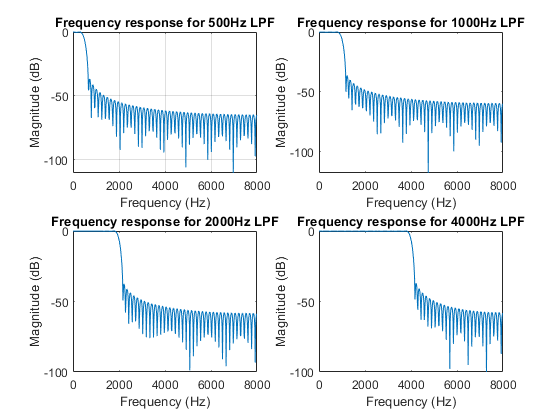

fc1 = 500;
sampling_frq = 16000;
Wn = (2/sampling_frq)*fc1;
b1 = fir1(100,Wn,'low',kaiser(101,3));

[h1,f] = freqz(b1,1,[],sampling_frq);
figure()
subplot(221)
plot(f,mag2db(abs(h1)))
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Frequency response for 500Hz LPF')
grid on

fc2 = 1000;
sampling_frq = 16000;
Wn = (2/sampling_frq)*fc2;
b2 = fir1(100,Wn,'low',kaiser(101,3));

[h2,f] = freqz(b2,1,[],sampling_frq);
subplot(222)
plot(f,mag2db(abs(h2)))
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Frequency response for 1000Hz LPF')


fc3 = 2000;
sampling_frq = 16000;
Wn = (2/sampling_frq)*fc3;
b3 = fir1(100,Wn,'low',kaiser(101,3));

[h3,f] = freqz(b3,1,[],sampling_frq);
subplot(223)
plot(f,mag2db(abs(h3)))
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Frequency response for 2000Hz LPF')


fc4 = 4000;
sampling_frq = 16000;
Wn = (2/sampling_frq)*fc4;
b4 = fir1(100,Wn,'low',kaiser(101,3));

[h4,f] = freqz(b4,1,[],sampling_frq);
subplot(224)
plot(f,mag2db(abs(h4)))
xlabel('Frequency (Hz)')
ylabel('Magnitude (dB)')
title('Frequency response for 4000Hz LPF')
grid off


% y_fil = filter(b,1,x1);
% fff = abs(fft(y_fil));
% 
% figure()
% plot(f1(1:length(x1)/2),Freqx1(1:length(x1)/2))
% figure()
% plot(f1(1:length(x1)/2),fff(1:length(x1)/2))

- Using low pass filter on input TIMIT signals and plot

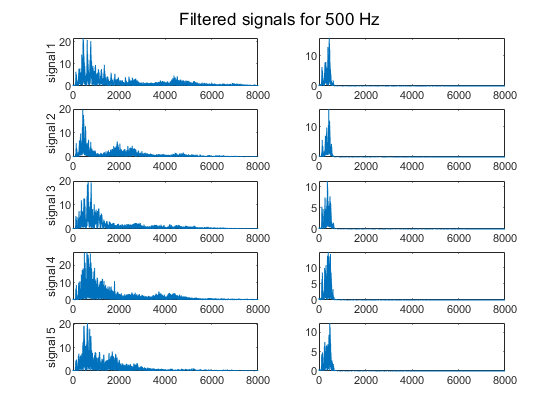

y_fil_11 = filter(b1,1,x1);
fff_11 = abs(fft(y_fil_11));
figure()
subplot(521)
plot(f1(1:length(x1)/2),Freqx1(1:length(x1)/2))
ylabel('signal 1')
subplot(522)
plot(f1(1:length(x1)/2),fff_11(1:length(x1)/2))

y_fil_12 = filter(b1,1,x2);
fff_12 = abs(fft(y_fil_12));
subplot(523)
plot(f2(1:length(x2)/2),Freqx2(1:length(x2)/2))
ylabel('signal 2')
subplot(524)
plot(f2(1:length(x2)/2),fff_12(1:length(x2)/2))

y_fil_13 = filter(b1,1,x3);
fff_13 = abs(fft(y_fil_13));
subplot(525)
plot(f3(1:length(x3)/2),Freqx3(1:length(x3)/2))
ylabel('signal 3')
subplot(526)
plot(f3(1:length(x3)/2),fff_13(1:length(x3)/2))

y_fil_14 = filter(b1,1,x4);
fff_14 = abs(fft(y_fil_14));
subplot(527)
plot(f4(1:length(x4)/2),Freqx4(1:length(x4)/2))
ylabel('signal 4')
subplot(528)
plot(f4(1:length(x4)/2),fff_14(1:length(x4)/2))

y_fil_15 = filter(b1,1,x5);
fff_15 = abs(fft(y_fil_15));
subplot(529)
plot(f5(1:length(x5)/2),Freqx5(1:length(x5)/2))
ylabel('signal 5')
subplot(5,2,10)
plot(f5(1:length(x5)/2),fff_15(1:length(x5)/2))
sgtitle('Filtered signals for 500 Hz')

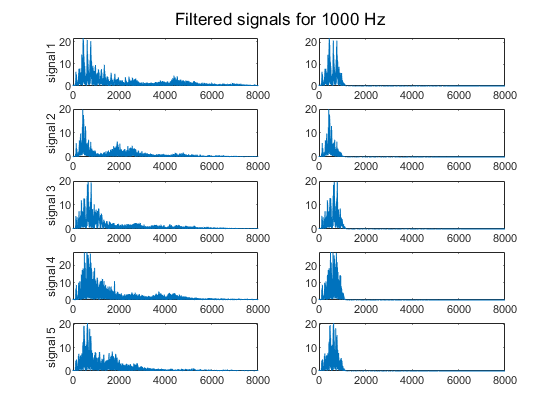



y_fil_21 = filter(b2,1,x1);
fff_21 = abs(fft(y_fil_21));
figure()
subplot(521)
plot(f1(1:length(x1)/2),Freqx1(1:length(x1)/2))
ylabel('signal 1')
subplot(522)
plot(f1(1:length(x1)/2),fff_21(1:length(x1)/2))

y_fil_22 = filter(b2,1,x2);
fff_22 = abs(fft(y_fil_22));
subplot(523)
plot(f2(1:length(x2)/2),Freqx2(1:length(x2)/2))
ylabel('signal 2')
subplot(524)
plot(f2(1:length(x2)/2),fff_22(1:length(x2)/2))

y_fil_23 = filter(b2,1,x3);
fff_23 = abs(fft(y_fil_23));
subplot(525)
plot(f3(1:length(x3)/2),Freqx3(1:length(x3)/2))
ylabel('signal 3')
subplot(526)
plot(f3(1:length(x3)/2),fff_23(1:length(x3)/2))

y_fil_24 = filter(b2,1,x4);
fff_24 = abs(fft(y_fil_24));
subplot(527)
plot(f4(1:length(x4)/2),Freqx4(1:length(x4)/2))
ylabel('signal 4')
subplot(528)
plot(f4(1:length(x4)/2),fff_24(1:length(x4)/2))

y_fil_25 = filter(b2,1,x5);
fff_25 = abs(fft(y_fil_25));
subplot(529)
plot(f5(1:length(x5)/2),Freqx5(1:length(x5)/2))
ylabel('signal 5')
subplot(5,2,10)
plot(f5(1:length(x5)/2),fff_25(1:length(x5)/2))
sgtitle('Filtered signals for 1000 Hz')

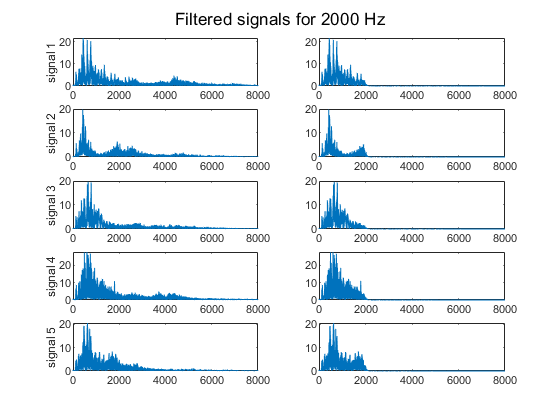



y_fil_31 = filter(b3,1,x1);
fff_31 = abs(fft(y_fil_31));
figure()
subplot(521)
plot(f1(1:length(x1)/2),Freqx1(1:length(x1)/2))
ylabel('signal 1')
subplot(522)
plot(f1(1:length(x1)/2),fff_31(1:length(x1)/2))

y_fil_32 = filter(b3,1,x2);
fff_32 = abs(fft(y_fil_32));
subplot(523)
plot(f2(1:length(x2)/2),Freqx2(1:length(x2)/2))
ylabel('signal 2')
subplot(524)
plot(f2(1:length(x2)/2),fff_32(1:length(x2)/2))

y_fil_33 = filter(b3,1,x3);
fff_33 = abs(fft(y_fil_33));
subplot(525)
plot(f3(1:length(x3)/2),Freqx3(1:length(x3)/2))
ylabel('signal 3')
subplot(526)
plot(f3(1:length(x3)/2),fff_33(1:length(x3)/2))

y_fil_34 = filter(b3,1,x4);
fff_34 = abs(fft(y_fil_34));
subplot(527)
plot(f4(1:length(x4)/2),Freqx4(1:length(x4)/2))
ylabel('signal 4')
subplot(528)
plot(f4(1:length(x4)/2),fff_34(1:length(x4)/2))

y_fil_35 = filter(b3,1,x5);
fff_35 = abs(fft(y_fil_35));
subplot(529)
plot(f5(1:length(x5)/2),Freqx5(1:length(x5)/2))
ylabel('signal 5')
subplot(5,2,10)
plot(f5(1:length(x5)/2),fff_35(1:length(x5)/2))
sgtitle('Filtered signals for 2000 Hz')

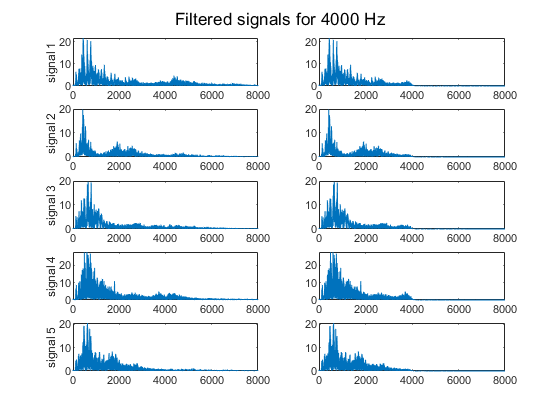



y_fil_41 = filter(b4,1,x1);
fff_41 = abs(fft(y_fil_41));
figure()
subplot(521)
plot(f1(1:length(x1)/2),Freqx1(1:length(x1)/2))
ylabel('signal 1')
subplot(522)
plot(f1(1:length(x1)/2),fff_41(1:length(x1)/2))

y_fil_42 = filter(b4,1,x2);
fff_42 = abs(fft(y_fil_42));
subplot(523)
plot(f2(1:length(x2)/2),Freqx2(1:length(x2)/2))
ylabel('signal 2')
subplot(524)
plot(f2(1:length(x2)/2),fff_42(1:length(x2)/2))

y_fil_43 = filter(b4,1,x3);
fff_43 = abs(fft(y_fil_43));
subplot(525)
plot(f3(1:length(x3)/2),Freqx3(1:length(x3)/2))
ylabel('signal 3')
subplot(526)
plot(f3(1:length(x3)/2),fff_43(1:length(x3)/2))

y_fil_44 = filter(b4,1,x4);
fff_44 = abs(fft(y_fil_44));
subplot(527)
plot(f4(1:length(x4)/2),Freqx4(1:length(x4)/2))
ylabel('signal 4')
subplot(528)
plot(f4(1:length(x4)/2),fff_44(1:length(x4)/2))

y_fil_45 = filter(b4,1,x5);
fff_45 = abs(fft(y_fil_45));
subplot(529)
plot(f5(1:length(x5)/2),Freqx5(1:length(x5)/2))
ylabel('signal 5')
subplot(5,2,10)
plot(f5(1:length(x5)/2),fff_45(1:length(x5)/2))
sgtitle('Filtered signals for 4000 Hz')

[xs1,Fs1s] = audioread("Track 49.wav");
[xs2,Fs2s] = audioread("Track 50.wav");
[xs3,Fs3s] = audioread("Track 51.wav");
[xs4,Fs4s] = audioread("Track 52.wav");
[xs5,Fs5s] = audioread("Track 53.wav");
[xs6,Fs6s] = audioread("Track 54.wav");
[xm1,Fs1m] = audioread("Track 55.wav");
[xm2,Fs2m] = audioread("Track 56.wav");
[xm3,Fs3m] = audioread("Track 57.wav");
[xm4,Fs4m] = audioread("Track 58.wav");
[xm5,Fs5m] = audioread("Track 59.wav");
[xm6,Fs6m] = audioread("Track 60.wav");

## Percentage of “Low-Energy” frames

- Break the frames into 10ms sub frames.

- Calculate the RMS power of the sub frames. 

- Compare it to the mean RMS power.

frame_m1 = zeros((2*(length(xm1)/Fs1m))-1,Fs1m);
MM_percent_m1 = zeros(1,63);
k=0;
for i = 1:(2*(length(xm1)/Fs1m))-1
    for j = 1:Fs1m
        frame_m1(i,j) = xm1(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(63,1);
for i = 1:63
    mean_RMS_f(i) = rms(frame_m1(i,:));
end
RMS_10ms_f = zeros(63,100);
for j =1:63
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_m1(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:63
    MM_percent_m1(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_m2 = zeros((2*(length(xm2)/Fs2m))-1,Fs2m);
MM_percent_m2 = zeros(1,67);
k=0;
for i = 1:(2*(length(xm2)/Fs2m))-1
    for j = 1:Fs2m
        frame_m2(i,j) = xm2(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(67,1);
for i = 1:67
    mean_RMS_f(i) = rms(frame_m2(i,:));
end
RMS_10ms_f = zeros(67,100);
for j =1:67
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_m2(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:67
    MM_percent_m2(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_m3 = zeros((2*(length(xm3)/Fs3m))-1,Fs3m);
MM_percent_m3 = zeros(1,39);
k=0;
for i = 1:(2*(length(xm3)/Fs3m))-1
    for j = 1:Fs3m
        frame_m3(i,j) = xm3(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(39,1);
for i = 1:39
    mean_RMS_f(i) = rms(frame_m3(i,:));
end
RMS_10ms_f = zeros(39,100);
for j =1:39
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_m3(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:39
    MM_percent_m3(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_m4 = zeros((2*(length(xm4)/Fs4m))-1,Fs4m);
MM_percent_m4 = zeros(1,31);
k=0;
for i = 1:(2*(length(xm4)/Fs4m))-1
    for j = 1:Fs4m
        frame_m4(i,j) = xm4(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(31,1);
for i = 1:31
    mean_RMS_f(i) = rms(frame_m4(i,:));
end
RMS_10ms_f = zeros(31,100);
for j =1:31
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_m4(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:31
    MM_percent_m4(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_m5 = zeros((2*(length(xm5)/Fs5m))-1,Fs5m);
MM_percent_m5 = zeros(1,57);
k=0;
for i = 1:(2*(length(xm5)/Fs5m))-1
    for j = 1:Fs5m
        frame_m5(i,j) = xm5(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(57,1);
for i = 1:57
    mean_RMS_f(i) = rms(frame_m5(i,:));
end
RMS_10ms_f = zeros(57,100);
for j =1:57
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_m5(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:57
    MM_percent_m5(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_m6 = zeros((2*(length(xm6)/Fs6m))-1,Fs6m);
MM_percent_m6 = zeros(1,183);
k=0;
for i = 1:(2*(length(xm6)/Fs6m))-1
    for j = 1:Fs6m
        frame_m6(i,j) = xm6(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(183,1);
for i = 1:183
    mean_RMS_f(i) = rms(frame_m6(i,:));
end
RMS_10ms_f = zeros(183,100);
for j =1:183
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_m6(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:183
    MM_percent_m6(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_s1 = zeros((2*(length(xs1)/Fs1s))-1,Fs1s);
SM_percent_s1 = zeros(1,45);
k=0;
for i = 1:(2*(length(xs1)/Fs1s))-1
    for j = 1:Fs1s
        frame_s1(i,j) = xs1(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(45,1);
for i = 1:45
    mean_RMS_f(i) = rms(frame_s1(i,:));
end
RMS_10ms_f = zeros(45,100);
for j =1:45
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_s1(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:45
    SM_percent_s1(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_s2 = zeros((2*(length(xs2)/Fs2s))-1,Fs2s);
SM_percent_s2 = zeros(1,43);
k=0;
for i = 1:(2*(length(xs2)/Fs2s))-1
    for j = 1:Fs2s
        frame_s2(i,j) = xs2(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(43,1);
for i = 1:43
    mean_RMS_f(i) = rms(frame_s2(i,:));
end
RMS_10ms_f = zeros(43,100);
for j =1:43
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_s2(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:43
    SM_percent_s2(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_s3 = zeros((2*(length(xs3)/Fs3s))-1,Fs3s);
SM_percent_s3 = zeros(1,41);
k=0;
for i = 1:(2*(length(xs3)/Fs3s))-1
    for j = 1:Fs3s
        frame_s3(i,j) = xs3(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(41,1);
for i = 1:41
    mean_RMS_f(i) = rms(frame_s3(i,:));
end
RMS_10ms_f = zeros(41,100);
for j =1:41
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_s3(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:41
    SM_percent_s3(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_s4 = zeros((2*(length(xs4)/Fs4s))-1,Fs4s);
SM_percent_s4 = zeros(1,47);
k=0;
for i = 1:(2*(length(xs4)/Fs4s))-1
    for j = 1:Fs4s
        frame_s4(i,j) = xs4(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(47,1);
for i = 1:47
    mean_RMS_f(i) = rms(frame_s4(i,:));
end
RMS_10ms_f = zeros(47,100);
for j =1:47
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_s4(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:47
    SM_percent_s4(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_s5 = zeros((2*(length(xs5)/Fs5s))-1,Fs5s);
SM_percent_s5 = zeros(1,41);
k=0;
for i = 1:(2*(length(xs5)/Fs5s))-1
    for j = 1:Fs5s
        frame_s5(i,j) = xs5(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(41,1);
for i = 1:41
    mean_RMS_f(i) = rms(frame_s5(i,:));
end
RMS_10ms_f = zeros(41,100);
for j =1:41
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_s5(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:41
    SM_percent_s5(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

frame_s6 = zeros((2*(length(xs6)/Fs6s))-1,Fs6s);
SM_percent_s6 = zeros(1,41);
k=0;
for i = 1:(2*(length(xs6)/Fs6s))-1
    for j = 1:Fs6s
        frame_s6(i,j) = xs6(j+k,1);
    end
    k = k+22050;
end
mean_RMS_f = zeros(41,1);
for i = 1:41
    mean_RMS_f(i) = rms(frame_s6(i,:));
end
RMS_10ms_f = zeros(41,100);
for j =1:41
    for i = 1:100
        RMS_10ms_f(j,i) = rms(frame_s6(j,(441*(i-1)+1):441*i));
    end
end
for i = 1:41
    SM_percent_s6(i) = size(find([RMS_10ms_f(i,:)<mean_RMS_f(i)]),2);
end

## Spectral Rolloff Point

- The 95th percentile of the power spectral distribution of each frame. 

MM_rolloff_m1 = zeros(1,63);
for i = 1:63
    MM_rolloff_m1(i) = prctile(pspectrum(frame_m1(i,:)),95);
end

MM_rolloff_m2 = zeros(1,67);
for i = 1:67
    MM_rolloff_m2(i) = prctile(pspectrum(frame_m2(i,:)),95);
end

MM_rolloff_m3 = zeros(1,39);
for i = 1:39
    MM_rolloff_m3(i) = prctile(pspectrum(frame_m3(i,:)),95);
end

MM_rolloff_m4 = zeros(1,31);
for i = 1:31
    MM_rolloff_m4(i) = prctile(pspectrum(frame_m4(i,:)),95);
end

MM_rolloff_m5 = zeros(1,57);
for i = 1:57
    MM_rolloff_m5(i) = prctile(pspectrum(frame_m5(i,:)),95);
end

MM_rolloff_m6 = zeros(1,183);
for i = 1:183
    MM_rolloff_m6(i) = prctile(pspectrum(frame_m6(i,:)),95);
end

SM_rolloff_s1 = zeros(1,45);
for i = 1:45
    SM_rolloff_s1(i) = prctile(pspectrum(frame_s1(i,:)),95);
end

SM_rolloff_s2 = zeros(1,43);
for i = 1:43
    SM_rolloff_s2(i) = prctile(pspectrum(frame_s2(i,:)),95);
end

SM_rolloff_s3 = zeros(1,41);
for i = 1:41
    SM_rolloff_s3(i) = prctile(pspectrum(frame_s3(i,:)),95);
end

SM_rolloff_s4 = zeros(1,47);
for i = 1:47
    SM_rolloff_s4(i) = prctile(pspectrum(frame_s4(i,:)),95);
end

SM_rolloff_s5 = zeros(1,41);
for i = 1:41
    SM_rolloff_s5(i) = prctile(pspectrum(frame_s5(i,:)),95);
end

SM_rolloff_s6 = zeros(1,41);
for i = 1:41
    SM_rolloff_s6(i) = prctile(pspectrum(frame_s6(i,:)),95);
end

## Spectral Centroid

- The weighted mean of the spectral power distribution. 

for i = 1:63
    MM_centroid_m1(i) = mean(pspectrum(frame_m1(i,:)));
end
for i = 1:67
    MM_centroid_m2(i) = mean(pspectrum(frame_m2(i,:)));
end
for i = 1:39
    MM_centroid_m3(i) = mean(pspectrum(frame_m3(i,:)));
end
for i = 1:31
    MM_centroid_m4(i) = mean(pspectrum(frame_m4(i,:)));
end
for i = 1:57
    MM_centroid_m5(i) = mean(pspectrum(frame_m5(i,:)));
end
for i = 1:183
    MM_centroid_m6(i) = mean(pspectrum(frame_m6(i,:)));
end


for i = 1:45
    SM_centroid_s1(i) = mean(pspectrum(frame_s1(i,:)));
end
for i = 1:43
    SM_centroid_s2(i) = mean(pspectrum(frame_s2(i,:)));
end
for i = 1:41
    SM_centroid_s3(i) = mean(pspectrum(frame_s3(i,:)));
end
for i = 1:47
    SM_centroid_s4(i) = mean(pspectrum(frame_s4(i,:)));
end

for i = 1:41
    SM_centroid_s5(i) = mean(pspectrum(frame_s5(i,:)));
end
for i = 1:41
    SM_centroid_s6(i) = mean(pspectrum(frame_s6(i,:)));
end

% MM_centroid_m1 = spectralCentroid(xm1(:,1), Fs1m, Window = hamming(Fs1m), OverlapLength = round(0.5*Fs1m));
% MM_centroid_m2 = spectralCentroid(xm2(:,1), Fs2m, Window = hamming(Fs2m), OverlapLength = round(0.5*Fs2m));
% MM_centroid_m3 = spectralCentroid(xm3(:,1), Fs3m, Window = hamming(Fs3m), OverlapLength = round(0.5*Fs3m));
% MM_centroid_m4 = spectralCentroid(xm4(:,1), Fs4m, Window = hamming(Fs4m), OverlapLength = round(0.5*Fs4m));
% MM_centroid_m5 = spectralCentroid(xm5(:,1), Fs5m, Window = hamming(Fs5m), OverlapLength = round(0.5*Fs5m));
% MM_centroid_m6 = spectralCentroid(xm6(:,1), Fs6m, Window = hamming(Fs6m), OverlapLength = round(0.5*Fs6m));
% 
% SM_centroid_s1 = spectralCentroid(xs1(:,1), Fs1s, Window = hamming(Fs1s), OverlapLength = round(0.5*Fs1s));
% SM_centroid_s2 = spectralCentroid(xs2(:,1), Fs2s, Window = hamming(Fs2s), OverlapLength = round(0.5*Fs2s));
% SM_centroid_s3 = spectralCentroid(xs3(:,1), Fs3s, Window = hamming(Fs3s), OverlapLength = round(0.5*Fs3s));
% SM_centroid_s4 = spectralCentroid(xs4(:,1), Fs4s, Window = hamming(Fs4s), OverlapLength = round(0.5*Fs4s));
% SM_centroid_s5 = spectralCentroid(xs5(:,1), Fs5s, Window = hamming(Fs5s), OverlapLength = round(0.5*Fs5s));
% SM_centroid_s6 = spectralCentroid(xs6(:,1), Fs6s, Window = hamming(Fs6s), OverlapLength = round(0.5*Fs6s));

## Spectral Flux

- The 2-norm of the frame-to-frame spectral amplitude difference vector.

- Follows the formula: $\left\|\left|X_i \right|-\left|X_{i+1} \right|\right\|$

ampdiff = [];
for i = 1:62
    ampdiff(i,:) = abs(pspectrum(frame_m1(i,:)) - pspectrum(frame_m1(1+i,:)));
end
ampdiff(63,:) = pspectrum(frame_m1(63,:));
MM_flux_m1 = zeros(1,63);
for i = 1:63
    MM_flux_m1(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:66
    ampdiff(i,:) = abs(pspectrum(frame_m2(i,:)) - pspectrum(frame_m2(1+i,:)));
end
ampdiff(67,:) = pspectrum(frame_m2(67,:));
MM_flux_m2 = zeros(1,67);
for i = 1:67
    MM_flux_m2(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:38
    ampdiff(i,:) = abs(pspectrum(frame_m3(i,:)) - pspectrum(frame_m3(1+i,:)));
end
ampdiff(39,:) = pspectrum(frame_m3(39,:));
MM_flux_m3 = zeros(1,39);
for i = 1:39
    MM_flux_m3(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:30
    ampdiff(i,:) = abs(pspectrum(frame_m4(i,:)) - pspectrum(frame_m4(1+i,:)));
end
ampdiff(31,:) = pspectrum(frame_m4(31,:));
MM_flux_m4 = zeros(1,31);
for i = 1:31
    MM_flux_m4(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:56
    ampdiff(i,:) = abs(pspectrum(frame_m5(i,:)) - pspectrum(frame_m5(1+i,:)));
end
ampdiff(57,:) = pspectrum(frame_m5(57,:));
MM_flux_m5 = zeros(1,57);
for i = 1:57
    MM_flux_m5(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:182
    ampdiff(i,:) = abs(pspectrum(frame_m6(i,:)) - pspectrum(frame_m6(1+i,:)));
end
ampdiff(183,:) = pspectrum(frame_m6(183,:));
MM_flux_m6 = zeros(1,183);
for i = 1:183
    MM_flux_m6(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:44
    ampdiff(i,:) = abs(pspectrum(frame_s1(i,:)) - pspectrum(frame_s1(1+i,:)));
end
ampdiff(45,:) = pspectrum(frame_s1(45,:));
SM_flux_s1 = zeros(1,45);
for i = 1:45
    SM_flux_s1(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:42
    ampdiff(i,:) = abs(pspectrum(frame_s2(i,:)) - pspectrum(frame_s2(1+i,:)));
end
ampdiff(43,:) = pspectrum(frame_s2(43,:));
SM_flux_s2 = zeros(1,43);
for i = 1:43
    SM_flux_s2(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:40
    ampdiff(i,:) = abs(pspectrum(frame_s3(i,:)) - pspectrum(frame_s3(1+i,:)));
end
ampdiff(41,:) = pspectrum(frame_s3(41,:));
SM_flux_s3 = zeros(1,41);
for i = 1:41
    SM_flux_s3(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:46
    ampdiff(i,:) = abs(pspectrum(frame_s4(i,:)) - pspectrum(frame_s4(1+i,:)));
end
ampdiff(47,:) = pspectrum(frame_s4(47,:));
SM_flux_s4 = zeros(1,47);
for i = 1:47
    SM_flux_s4(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:40
    ampdiff(i,:) = abs(pspectrum(frame_s5(i,:)) - pspectrum(frame_s5(1+i,:)));
end
ampdiff(41,:) = pspectrum(frame_s5(41,:));
SM_flux_s5 = zeros(1,41);
for i = 1:41
    SM_flux_s5(i) = norm(ampdiff(i,:));
end

ampdiff = [];
for i = 1:40
    ampdiff(i,:) = abs(pspectrum(frame_s6(i,:)) - pspectrum(frame_s6(1+i,:)));
end
ampdiff(41,:) = pspectrum(frame_s6(41,:));
SM_flux_s6 = zeros(1,41);
for i = 1:41
    SM_flux_s6(i) = norm(ampdiff(i,:));
end

## Zero-Crossing Rate

All BC distances in report:

- BC distance for the Percentage of low energy: 0.1706

- BC distance for the Spectral Rolloff Point: 0.3577

- BC distance for the Spectral Centroid: 0.1706

- BC distance for the Spectral Flux: 0.4259

- BC distance for the Zero crossing rate: 0.2216

Feature with highest value is best feature for seperability. 

And for Differentiation between speech and music signals Spectral Flux is the best feature. 

zcd = dsp.ZeroCrossingDetector;

frame_m1T = frame_m1';
MM_zcr_m1 = zeros(1,63);
for i = 1:63
    MM_zcr_m1(i) = zcd(frame_m1T(:,i));
end

frame_m2T = frame_m2';
MM_zcr_m2 = zeros(1,67);
for i = 1:67
    MM_zcr_m2(i) = zcd(frame_m2T(:,i));
end

frame_m3T = frame_m3';
MM_zcr_m3 = zeros(1,39);
for i = 1:39
    MM_zcr_m3(i) = zcd(frame_m3T(:,i));
end

frame_m4T = frame_m4';
MM_zcr_m4 = zeros(1,31);
for i = 1:31
    MM_zcr_m4(i) = zcd(frame_m4T(:,i));
end

frame_m5T = frame_m5';
MM_zcr_m5 = zeros(1,57);
for i = 1:57
    MM_zcr_m5(i) = zcd(frame_m5T(:,i));
end

frame_m6T = frame_m6';
MM_zcr_m6 = zeros(1,183);
for i = 1:183
    MM_zcr_m6(i) = zcd(frame_m6T(:,i));
end

frame_s1T = frame_s1';
SM_zcr_s1 = zeros(1,45);
for i = 1:45
    SM_zcr_s1(i) = zcd(frame_s1T(:,i));
end

frame_s2T = frame_s2';
SM_zcr_s2 = zeros(1,43);
for i = 1:43
    SM_zcr_s2(i) = zcd(frame_s2T(:,i));
end

frame_s3T = frame_s3';
SM_zcr_s3 = zeros(1,41);
for i = 1:41
    SM_zcr_s3(i) = zcd(frame_s3T(:,i));
end

frame_s4T = frame_s4';
SM_zcr_s4 = zeros(1,47);
for i = 1:47
    SM_zcr_s4(i) = zcd(frame_s4T(:,i));
end

frame_s5T = frame_s5';
SM_zcr_s5 = zeros(1,41);
for i = 1:41
    SM_zcr_s5(i) = zcd(frame_s5T(:,i));
end

frame_s6T = frame_s6';
SM_zcr_s6 = zeros(1,41);
for i = 1:41
    SM_zcr_s6(i) = zcd(frame_s6T(:,i));
end

SM = [SM_percent_s1' SM_rolloff_s1' SM_centroid_s1' SM_flux_s1' SM_zcr_s1';
      SM_percent_s2' SM_rolloff_s2' SM_centroid_s2' SM_flux_s2' SM_zcr_s2';
      SM_percent_s3' SM_rolloff_s3' SM_centroid_s3' SM_flux_s3' SM_zcr_s3';
      SM_percent_s4' SM_rolloff_s4' SM_centroid_s4' SM_flux_s4' SM_zcr_s4';
      SM_percent_s5' SM_rolloff_s5' SM_centroid_s5' SM_flux_s5' SM_zcr_s5';
      SM_percent_s6' SM_rolloff_s6' SM_centroid_s6' SM_flux_s6' SM_zcr_s6';];

MM = [MM_percent_m1' MM_rolloff_m1' MM_centroid_m1' MM_flux_m1' MM_zcr_m1';
      MM_percent_m2' MM_rolloff_m2' MM_centroid_m2' MM_flux_m2' MM_zcr_m2';
      MM_percent_m3' MM_rolloff_m3' MM_centroid_m3' MM_flux_m3' MM_zcr_m3';
      MM_percent_m4' MM_rolloff_m4' MM_centroid_m4' MM_flux_m4' MM_zcr_m4';
      MM_percent_m5' MM_rolloff_m5' MM_centroid_m5' MM_flux_m5' MM_zcr_m5';
      MM_percent_m6' MM_rolloff_m6' MM_centroid_m6' MM_flux_m6' MM_zcr_m6';];

BC_percent = BCdistance(SM(:,1),MM(:,1));
BC_rolloff = BCdistance(SM(:,2),MM(:,2));
BC_centroid = BCdistance(SM(:,3),MM(:,3));
BC_flux = BCdistance(SM(:,4),MM(:,4));
BC_zcr = BCdistance(SM(:,5),MM(:,5));

BC_SM_MM = BCdistance(SM,MM)

BC_SM_MM = 0.8692